# **Bayesian Optimisation Example**

**SECTION 1.0**

Goal: *maximise the function f(x) = x.*sin( x );  in the interval [0, 10]*

clear
close all
x = linspace( 0, 10, 501 ).';
f = x.*sin( x );


Extract 7 points for training an initial surrogate model & plot the results:

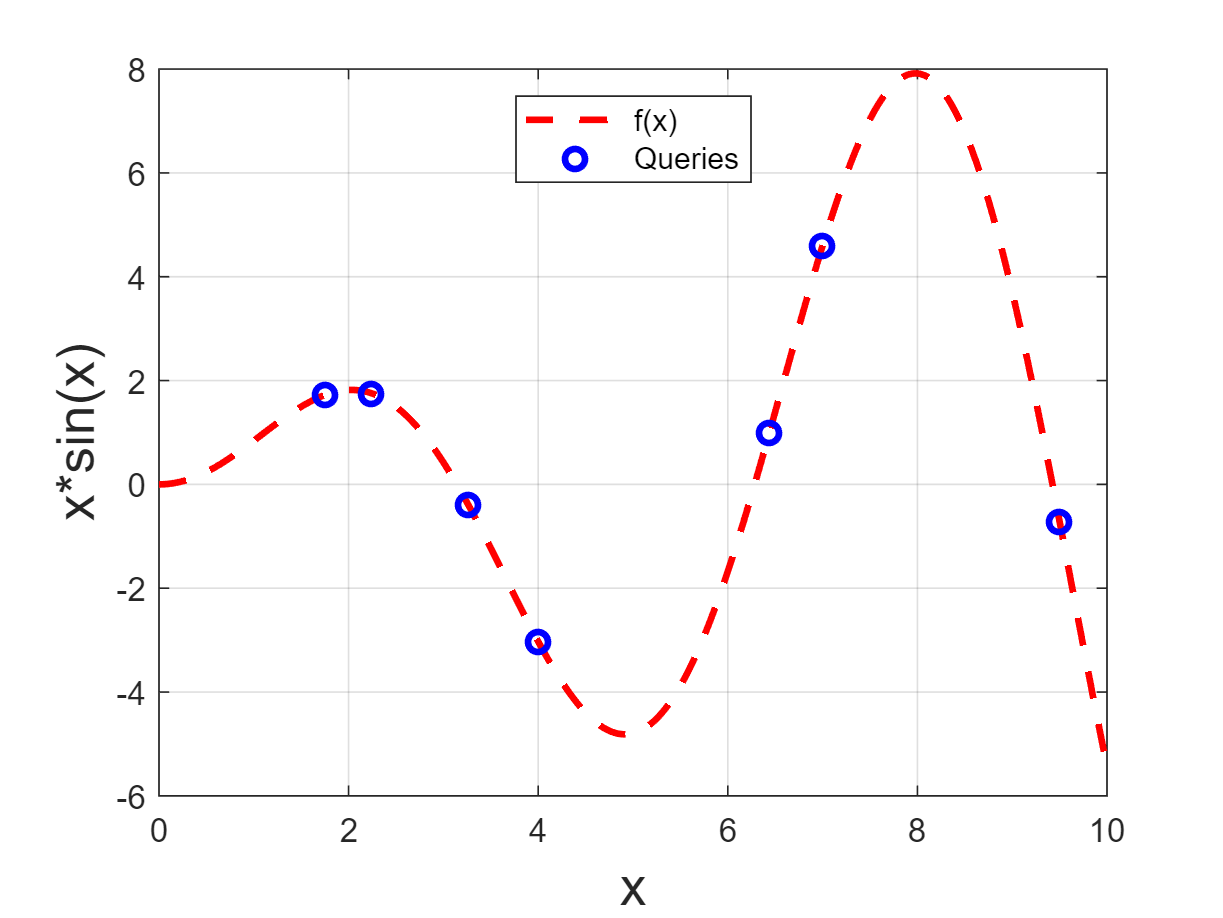

X = [ 9.5, 2.24, 4, 1.76, 3.26, 6.44, 7.0 ].';
Y = X .* sin( X );
plot( x, f, 'r--', X, Y, 'bo', 'LineWidth', 2 );
grid on
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
legend( "f(x)", "Queries", "Location", "north")

**SECTION 2.0**

Create the Bayesian Optimisation object. Assume a Gaussian Process Regression model and the Upper Confidence Bound acquisition function

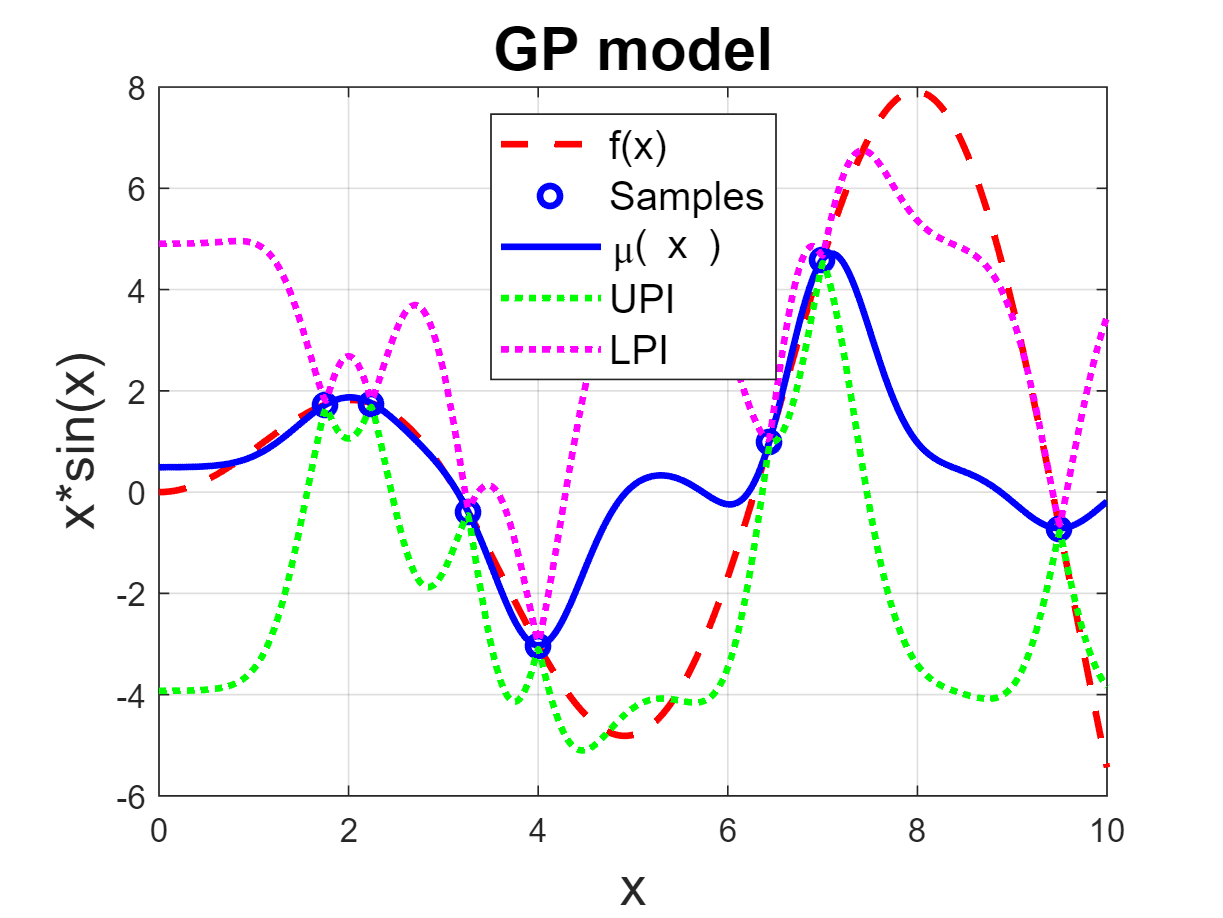

B = bayesOpt( "gpr", "ucb");
B = B.conDataCoding( 0, 10 );
B = B.setTrainingData( X, Y );
[ Yp, ~, Yint] = B.predict( x, 0.05 );
close all
figure;
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', 'LineWidth', 2);
grid on
legend( "f(x)", "Samples", "\mu( x )", 'Location', 'north', "FontSize", 12 );
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
title( "GP model", "FontSize", 18 );
hold on;
plot(  x, Yint( :,1 ), 'g:', x, Yint( :,2 ), 'm:', 'LineWidth', 2);
legend( "f(x)", "Samples", "\mu( x )", "UPI", "LPI", 'Location', 'north', "FontSize", 12 );

**SECTION 3.0**

Minimise -UCB(x)

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -4.613453e+00    0.000e+00    2.420e+00
    1       7   -4.699475e+00    0.000e+00    2.888e+00    3.026e-01
    2       9   -4.905481e+00    0.000e+00    5.708e-01    1.646e-01
    3      11   -4.912293e+00    0.000e+00    6.686e-02    2.716e-02
    4      13   -4.912389e+00    0.000e+00    7.202e-04    2.848e-03
    5      15   -4.912389e+00    0.000e+00    1.090e-06    3.102e-05
    6      17   -4.912389e+00    0.000e+00    8.322e-09    4.688e-08

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the 

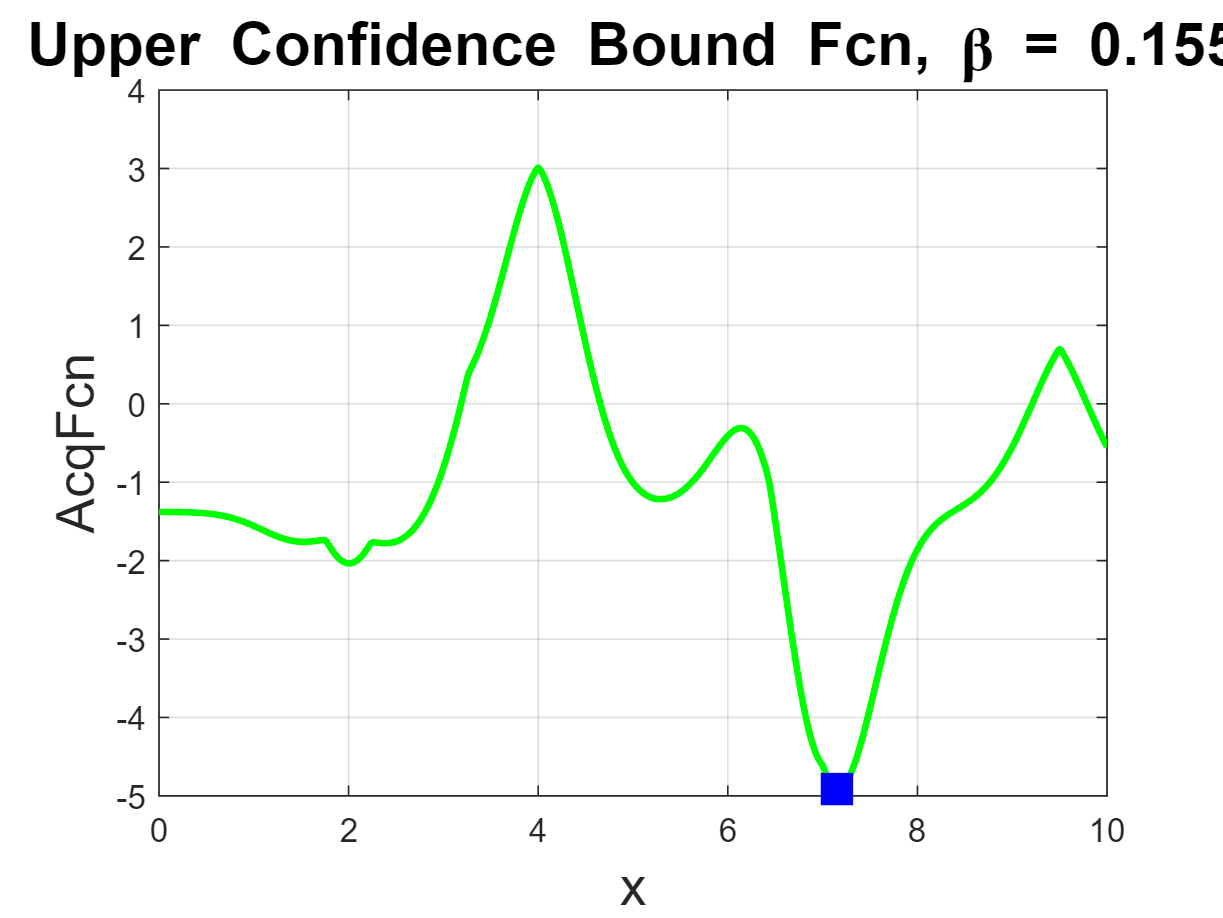

U = B.AcqObj;
figure;
A = U.evalFcn( x, U.Beta );
plot( x, A, 'g-', 'LineWidth', 2); grid on
xlabel( "x", "FontSize", 16 )
ylabel( "AcqFcn", "FontSize", 16 )
Tstr = sprintf( "Upper Confidence Bound Fcn, \\beta = %4.3f", U.Beta );
title( Tstr, "FontSize", 18 ); 
hold on, plot( B.Xnext, B.AcqObj.evalFcn( B.Xnext ), "bs", "MarkerSize", 12, "MarkerFaceColor", "blue" );
grid on
hold off

**SECTION 4.0**

Query f(x) at the suggested value and update the GP model

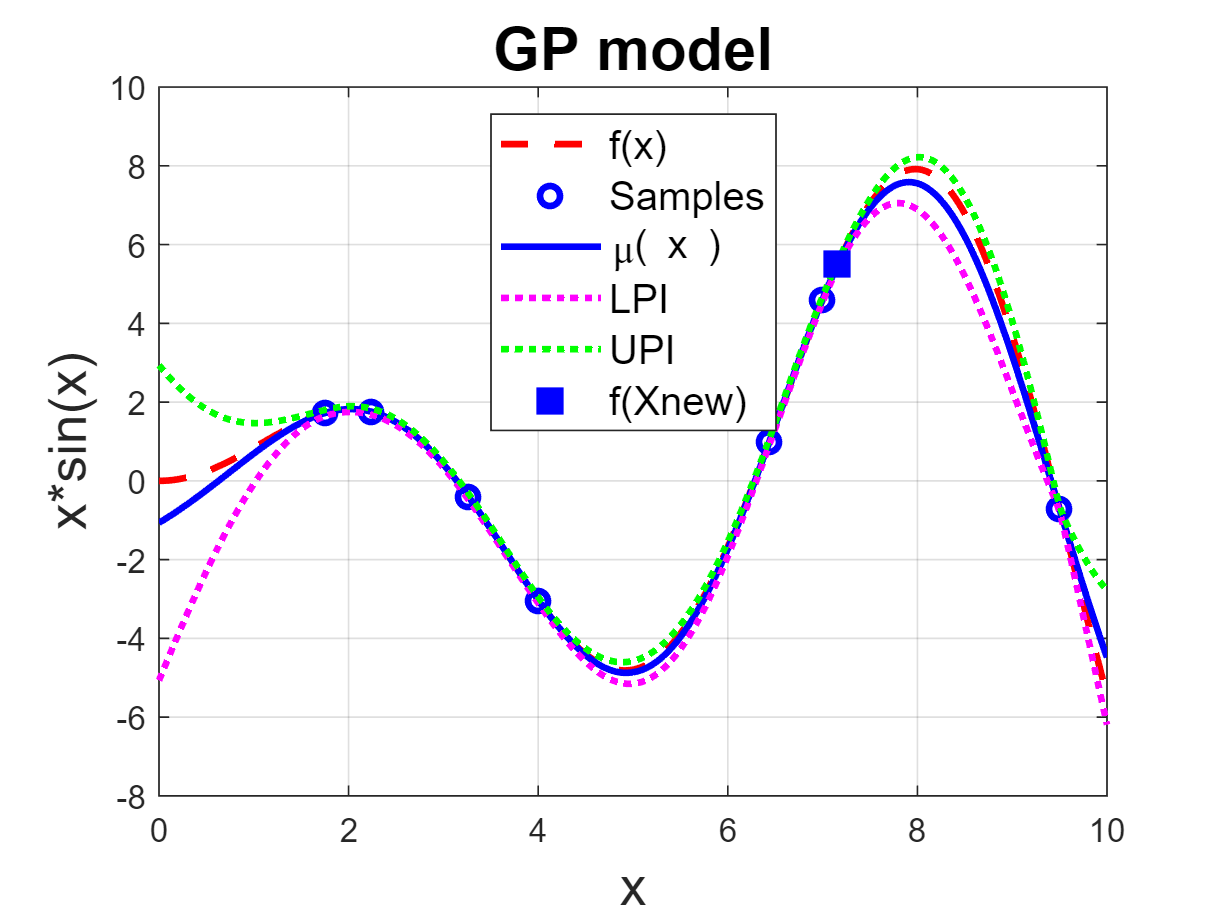

figure;
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
[ Yp, ~, Yint ] = B.predict( x );
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north', "FontSize", 12 );
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
title( "GP model", "FontSize", 18 );

**SECTION 5.0**

Iteration 2. Now re-optimise the acquisition function and add the new query to the training data and retrain the surrogate model.

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -5.517704e+00    0.000e+00    5.176e+00
    1       6   -6.564603e+00    0.000e+00    4.202e+00    1.294e+00
    2       8   -7.676225e+00    0.000e+00    4.350e-01    5.797e-01
    3      10   -7.687908e+00    0.000e+00    6.031e-03    5.439e-02
    4      12   -7.687910e+00    0.000e+00    2.643e-05    7.438e-04
    5      14   -7.687910e+00    0.000e+00    5.186e-07    3.246e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints a

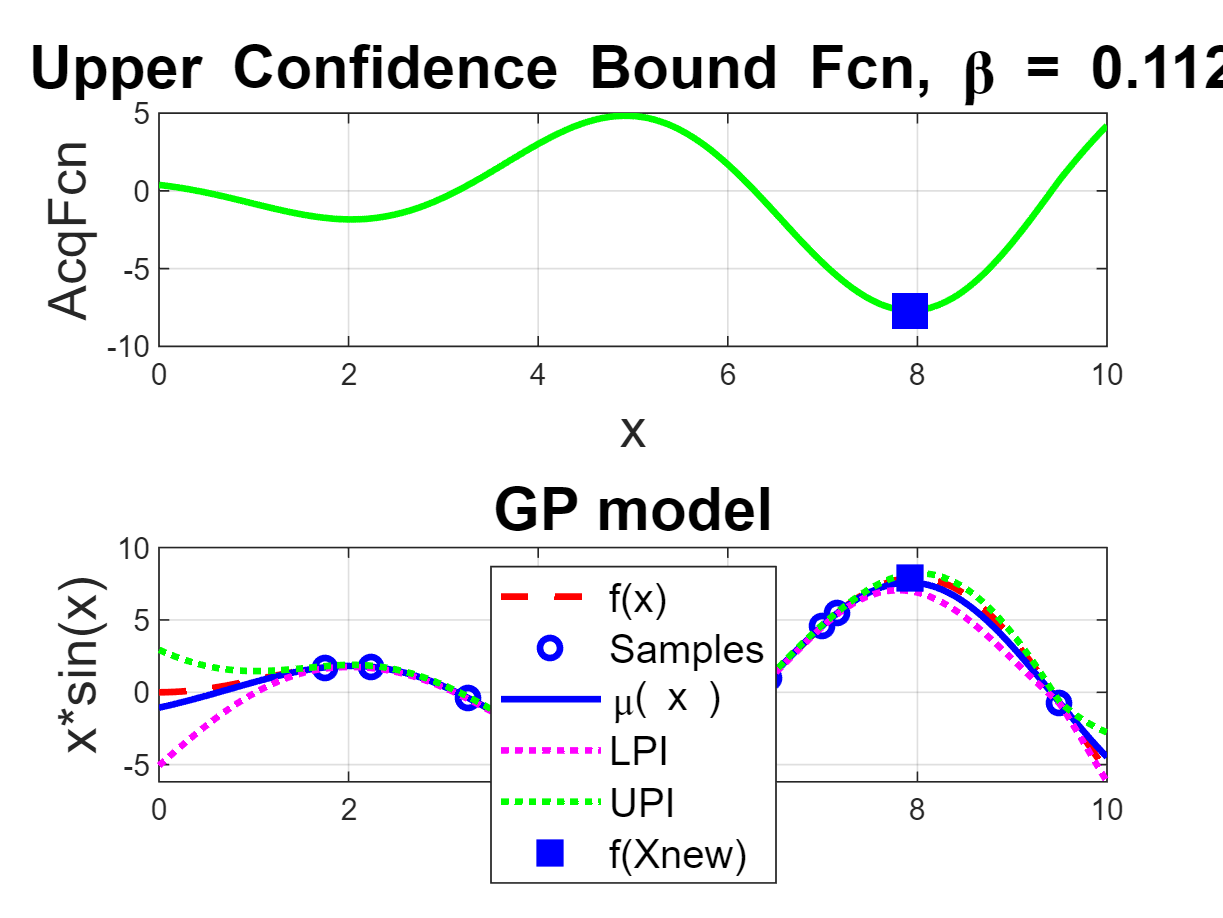

figure;
Xnew = B.Xnext;
subplot(2,1,1), plot( x, B.AcqObj.evalFcn( x ), 'g-', Xnew, B.AcqObj.evalFcn( Xnew ), 'bs', 'MarkerSize', 12,'LineWidth', 2, 'MarkerFaceColor','blue');
grid on
xlabel( "x", "FontSize", 16 )
ylabel( "AcqFcn", "FontSize", 16 )
Tstr = sprintf( "Upper Confidence Bound Fcn, \\beta = %4.3f", U.Beta );
title( Tstr, "FontSize", 18 ); 
subplot(2,1,2)
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north', "FontSize", 12 );
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
title( "GP model", "FontSize", 18 );